# **Computing instantaneous phase**

Leonardo Lancia

Laboratoire Parole et Langage 

CNRS / Aix Marseille Univesité

leonardo.lancia@cnrs.fr

The approach described here can be applied in the analysis of cyclic smooth signals that have one peak per cycle and whose amplitude changes slowly relatively to the signal's frequency. This kind of signals can generally be approximated by a sinusoid. When dealing with processes producing sinusoidal signals, it is very common to characterize the relations between different processes in terms of their instantaneous phase. This quantity represents the position of each process in its own cycle at each instant. Since its interpretation does not depend on the shape of the cycles, this quantity can be used to characterize the relations between patterns of activity that are completely differents. This tutorial is aimed at introducing the instantaneous phase and its computation.

## **Instantaneous phase of a sinusoid**

A sinusoidal signal is one whose value at instant $t$ can be expressed as the cosine (or the sine) of an angle multiplied by a gain coefficient. Let’s consider for example the signal *c(t)* given by:

$c\left(t\right)=a\left(t\right)\times \cos \left(\phi \left(t\right)\right)$                                                                    (1)

Such a signal at time t is equal to the cosine of the angle $\phi \left(t\right)$ multiplied by a amplitude parameter $a\left(t\right)$, both changing over time (as a function of t). The amplitude and the phase angle are called polar coordinates. Usually sinusoids represented on a computer are sampled at constantly spaced points in time (where the sampling frequency is $\frac{1}{\Delta t}$ and the sampling period, the interval between consecutive values, is $\Delta t$). Such a sinusoid is represented by 

$\left.c{\left(n\right)}=a\left(n\right)\times \mathrm{c}\mathrm{o}\mathrm{s}\left(\phi {\left(n\right)}\right)$                                                                    (2)

where *n* is an integer.

**The point on a circle**         $c\left(n\right)$ can also be defined as the horizontal coordinate of a point moving counter-clockwise along a circle centred at the origin of the axes having radius equal to the amplitude coefficient  . 

**The phase angle**              The motion of the point is determined by the phase angle $\phi \left(n\right)$ that is formed by the horizontal axis and the line connecting the point to the origin of the axes. $\phi$ being an angle, it rotates counter clockwise from 0 to 2$\pi$ radians when t increases, and it restarts from 0 at each cycle.

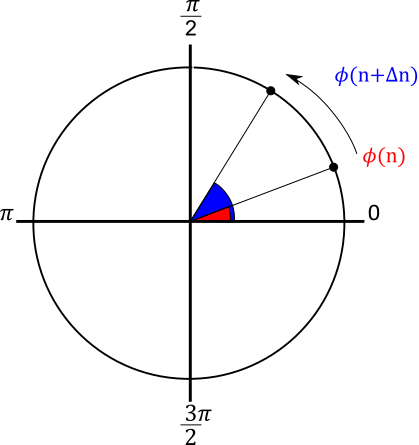

If $a\left(n\right)$ is constant and equal to one, when the angle $\phi \left(n\right)$ is 0 the cosine is at its maximum value (1) and starts to decrease until the angle reaches $\pi$  (where it’s found at its minimum val: -1). Then it starts increasing as $\phi$ moves from 0  to two 2$\pi$. The values of the angle $\phi$ moving from 0 to 2$\pi$ in each cycle are shown over time in the topmost panel of the figure. While the cosine of $\phi$  is depicted in the second panel from the top.

Note that if the horizontal coordinate of the point is the cosine of the phase angle $\phi$  multiplied by the amplitude value $a\left(n\right)$, the vertical coordinate is the sine of the same angle multiplied by the same amplitude value.

clear
addpath(genpath('./gen_utils'))
addpath('get_phase/utils')

warning off

sr=1000;
n=[1:5000]./sr;
A=-0.5.*(n.^3-5.*n.^2);
phi=wrapTo2Pi(2*pi*n);
c=A.*cos(phi); % A.*sin(2*pi*t+pi); cf. eq. (2) below %
a(1)=subplot(411);
plot(n,phi)
ylabel('$\phi(n)$','Interpreter','latex')
a(2)=subplot(412);
plot(n,cos(phi));
ylabel('$\cos(\phi(n))$','Interpreter','latex')
a(2)=subplot(413);
plot(n,A)
ylabel('A(n)')
a(3)=subplot(414);
plot(n,c);
ylabel('c(n)')
xlabel('Time (sec)')
linkaxes(a,'x')

**Time varying amplitude**	The amplitude of the oscillation $a\left(n\right)$ (and the radius of the circle) can change over time. The values of $c\left(n\right)$ (bottom panel) correspond to the values of the angle's cosine (second panel from top) multiplied by $a\left(n\right)$ (third panel from top). 

**Complex notation                  **In addition to being described in polar notation via an amplitude and a phase value, sinusoids can be described via cartesian coordinates (the height and the horizontal position of the point). This representation is often provided in complex notation:

$c{\left(n\right)}=A{\left(n\right)}+j\times B\left(n\right)$                                                                          (3)

Where the real part $A\left(n\right)=a\left(n\right)\times \cos \left(\phi \left(n\right)\right)$and the imaginary part $B\left(n\right)=a\left(n\right)\times \sin \left(\phi \left(n\right)\right)$ represent respectively the horizontal and vertical coordinates of the point. The real part corresponds to the observed sinusoid and the imaginary part is equal to the sine function of the same angle multiplied by $a\left(n\right)$.

$\begin{array}{l}
c{\left(n\right)}=a{\left(n\right)}\times \cos {\left(\phi {\left(n\right)}\right)}+j\times a{\left(n\right)}\times \sin {\left(\phi {\left(n\right)}\right)}=\ldotp \ldotp \ldotp \\
a{\left(n\right)}\times {\left[\cos {\left(\phi {\left(n\right)}\right)}+j\times \sin {\left(\phi {\left(n\right)}\right)}\right]}
\end{array}$                            (4)

Knowing the cartesian coordinates of out points allows us to obtain the polar coordinates (amplitude and phase) as:

$a\left(n\right)=\sqrt{{A\left(n\right)}^2 +{B\left(n\right)}^2 }$,                                                                       (5)

expressing the fact that the magnitude of the sinusoid corresponds to the distance of the point from the origin (i.e. to the radius of the circle, that can change over time).

$\phi \left(n\right)=\tan^{-1} {\left(\frac{B\left(n\right)}{A\left(n\right)}\right)}$,                                                                           (6)

expressing the fact that its phase is represented by the angle $\phi$ between the point and the horizontal axis.

**Sinusoid period and frequency** The phase angle of the sinusoid described so far has a constant rate such that a complete cycle is observed after $2\times \pi$ time steps. The period of the sinusoid is the duration of a cycle, its frequency is the number of cycles observed in each second, if it is expressed in Hertz, or the number of radians (i.e. the fraction of  $2\times \pi$) covered at each sample . 

The usual way to characterize a sinusoid by specifying its amplitude, frequency and phase is through:

$c{\left(n\right)}=a\left(n\right)\times cos\left(\omega \left(n\right)\times n\ -\ \phi_0 \right)$                                                       (7)

Where $a\left(n\right)$ is the time varying amplitude, $\omega \left(n\right)$ is the time varying frequency and $\phi_0$ is its initial phase value (the phase angle when $n=0$). If the sinusoid’s frequency is constant (i.e. $\omega \left(n\right)=\omega ,\ \forall \ n\ \in \left\lbrace 1,\dots ,N\right\rbrace$, with N being the length of the time series in number of samples, the phase of the sinusoid at time sample n is $\phi {\left(n\right)}=\omega \times n-\phi_0$.

**Modeling oscillations via sinusoids**  In principle all oscillatory cyclic signals that change smoothly over time and that have one peak per cycle can be modeled through a sinusoid whose phase and amplitude are allowed to change over time. So in the analysis of a signal via a sinusoidal model we are interested in extracting the phase and the amplitude over time. This task is performed by representing the observed time-series via an analitic signal.

**Analitic signals**         The horizontal and vertical coordinates (also referred to as the cartesian coordinates) of our points are obtained through scaling the cosines and the sines of the angle $\phi \left(n\right)$by the amplitude value $a\left(n\right)$. 

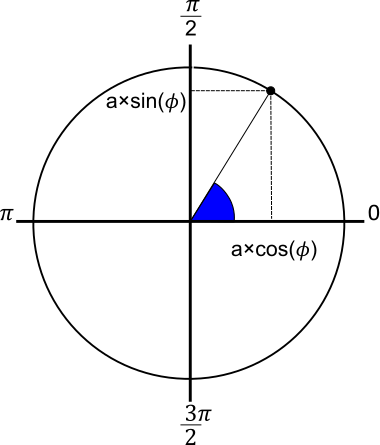

But the sine function is just a cosine function lagged by $\frac{\pi }{2}$:

$\sin \left(\phi \left(n\right)\right)=\mathrm{cos}\left(n-\frac{\pi }{2}\right)$                                                                        (8)

figure;
subplot(311)
plot(n,cos(phi))
ylabel('$\cos(\phi(n))$','Interpreter','latex') 
subplot(312)
plot(n,sin(phi))
ylabel('$\sin(\phi(n))$','Interpreter','latex') 
subplot(313)
plot(n,cos(phi-pi/2))
ylabel('$\cos(\phi(n-\pi/2))$','Interpreter','latex') 
xlabel ('Time (sec.)')

In other words, a sinusoidal signal ( a cosine function of time scaled by $a\left(n\right)$) can also be represented by a point moving on a circle whose horizontal and vertical coordinates are the sinusoidal signal itself and a copy of that signal lagged by $\frac{\pi }{2}$.

figure;
subplot(3,2,[1 3])
plot(A.*cos(phi),A.*sin(phi))
ylabel('$j \sin(\phi(t))$','Interpreter','latex')
xlabel('$\cos(\phi(t))$','Interpreter','latex')
title('complex representation of the sinusoid')

subplot(3,2,[5 6])
plot(n,A.*cos(phi))
hold on
plot(n,A.*sin(phi))
xlabel('Time (s)')
title('real (blue) and complex (red) components over time')

Once we have the cartesian coordinates of our point as a function of t, we can represent our sinusoid via polar coordinates, which is to say as an amplitude and a phase angle changing through time. So, if we see a sinusoid and we want to get its phase and amplitude we just need to use a lagged copy of it to build an analytic signal (complex representation). 

Well,… not really. To obtain the analytic signal we must know the length of its cycles (so that we can lag our signal by 1/4 of the cycles’ length). This implies that the cycle’s length should not change over time, which was the case for the sinusoid in 1) or 2) but, but which is not the general case represented in 7). 

## Getting the analytic form of sinusoidal functions

Luckily enough, given an observed sinusoid, there are several approaches to obtain its real and imaginary part (also known as the quadrature signal) which permits then to get the time varying amplitude and phase, A widely adopted method is based on the Hilbert transform which, given an univariate input time series, returns its quadratue signal and thus permits obtaining a two-dimensional time-series whose first dimension corresponds to its real part (i.e. the observed time series) and the other to its imaginary part (something similar to the real part but shifted by $\frac{\pi }{2}$).

anSignal=hilbert(c);
figure;
plot(n,real(anSignal));
hold on;
plot(n,imag(anSignal));
xlabel ('Time (sec.)')
title('Real and complex components as derived via the Matlab hilbert. function')

Note that even if the output of the matlab command hilbert.m is the analytic signal itself, strictly speaking the output of the Hilbert transform is the quadrature signal. From that representation we can compute the phase and the amplitude with the following commands:

obsPhi=angle(anSignal); % get the phase
obsPhi=wrapToPi(obsPhi); % unwrap the phase (make it vary between -pi and pi)
obsAmp=abs(anSignal); % get the amplitude

This means that in Matlab if $x$ is a complex valued signal, the output  the command **angle(x)** is $\mathrm{atan}\left(\mathrm{re}\left(x\right)/\mathrm{im}\left(x\right)\right)$and the output of **abs(x)** is $\sqrt{{\mathrm{re}\left(x\right)}^2 +{\mathrm{im}\left(\cdot \right)}^3 }$, with the functions $\mathrm{re}\left(\cdot \right)$ and $\mathrm{im}\left(\cdot \right)$respectively computing the real and the imaginary parts of their complex valued argument.

figure;
plot(n,phi)
hold on
plot(n,obsPhi)
title('real (blue) and (red) estimated phase angles over time')
xlabel ('Time (sec.)')
figure;
plot(n,A)
hold on
plot(n,obsAmp)
title('real (blue) and (red) estimated amplitude values over time')
xlabel ('Time (sec.)')

The only issue here is that in order to give interpretable phase values the Hilbert transform must be applied to signals whose amplitude changes are much slower than the changes in phase and nested cycles are not allowed. Not to talk of when there is variability in the shapes of the cycles.... An example?

dataIn=load('./data/cl_pata_2.mat');
sr=dataIn.samplerate;
artNames={'lang-aY'};%,'lev-iY','jawY','lang-aX','lev-iX','jawX'};%labels of the 

artdata=[];
for i=1:length(artNames)% recover the data corresponding to the labels in artNames
    mySig(:,i)=dataIn.data(:,strmatch(artNames{i},dataIn.descriptor,'exact'));
end
artTime=[1:size(mySig,1)]./sr;%build time steps vector

%filter parameters
hiCut=10; %Max allowed frequency
filtLen=1000;%filter order
hiCutNorm=hiCut./( sr/2 );% normalized cut-off
b1=fir1(filtLen,hiCutNorm,'low');% get filter coefficients

filtSig=filter(b1,1,mySig);%apply filter

filtSig=filtSig(filtLen/2+1:end);%correct filter delay
artTimeFilt=artTime(filtLen/2+1:end);%correct filter delay

filtSig=zscore(filtSig);%at least now it oscillates around 0 like a real sinusoid.

figure;
plot(artTimeFilt,filtSig)
title('Tongue tip''s vertical movement over time.')

analiticSignal=hilbert(filtSig);% get analytic signal

figure;
plot(artTimeFilt, real(analiticSignal))%plot real part
hold on;
plot(artTimeFilt, imag(analiticSignal))%plot imaginary part
xlim([6 8])
title('Real and complex components of tongue tip''s vertical movement.')
xlabel ('Time (sec.)')
figure
c(1)=subplot(211);
plot(artTimeFilt,filtSig);
title('Tongue tip''s vertical movement over time.')
c(2)=subplot(212);
hPhase=wrapTo2Pi(angle(analiticSignal)); % extract Hilbert phase
plot(artTimeFilt,hPhase)
title('Estimated phase of tongue tip''s vertical movement.')
xlabel ('Time (sec.)')
linkaxes(c,'x')
xlim([6 8])

## Huang's approach

If we have a sinusoidal signal oscillating around zero we can usually normalize its cycles so to vary between 0 and one. For example Huang et al (2009) propose to submit the signal to empirical mode decomposition. This step permits obtaining several sinusoids centered around zero called Independent mode functions (or IMFs). 

decomp=emd(filtSig); %apply EMD
figure;
stackedplot(decomp');

The cycles of one IMF (here the second IMF) whill have their phase locked to that of the input signal. Its amplitude can be normalized so that it oscillates between -1 and 1 at each cycle in the following way: 

First the absolute value of each local maximum is computed, then the obtained amplitude values are interpolated so to obtain a time series sampled at the same time points as the original time series; finally, each sample of the original time series is divided by the corresponding value in the interpolated signal. The procedure is iterated by taking as input the obtained signal until none of its peak values exceeds the value of one (or until a generally small maximum number of iterations is reached).


filtSigNorm=normalize_env_peaks(decomp(2,:)'); %cycle's amplitude normalization
figure;
plot(artTimeFilt,decomp(2,:))

hold on
plot(artTimeFilt,filtSigNorm)

title('Second IMF (blue) and its version with amplitude-normalized cycles')
xlabel ('Time (sec.)')

Then we can submit the constant amplitude time series to an algorithm permitting to obtain its imaginary part (e.g. Hilbert transform method, direct quadrature method) and to compute the instantaneous phase. 

figure;
subplot(211)
plot(artTimeFilt,filtSig)
title('Amplitude-normalized Second IMF ')
xlabel ('Time (sec.)')
subplot(212)
plot(wrapTo2Pi(angle(hilbert(filtSigNorm))))

## Band pass filtering the signal to skip EMD

The problem with using EMD is that we need to individuate the IMF that captures the cycles of interest in the observed signal, and this EMD may also change from one signal to the other. Moreover EMD is not always capable to isolate the oscillation of interest (see companion paper).

Actually, when working with band-pass filtered signals, in many cases the application of EMD may not be required.

Let's try with the syllabic component of a speech signal's acoustic energy modulation.

Let's load an audio signal and compute its acoustic energy 

[audioIn,audioSr]=audioread('./data/mamine_cont_2.wav');
audioIn=audioIn(:,1); % get first channel

audioT=[1:length(audioIn)]./audioSr;%build time steps vector

%RMS parameters
winLenS=0.025; %window length (secs)
winStepS=0.005; %step size (secs)
rmsSr=1/winStepS; %RMS sampling rate
winLen=floor(winLenS.*audioSr); %window length (frames)
winStep=winStepS.*audioSr; %step size (frames)
winOver=winLen-winStep; %overlap between consecutive windows size (frames)

%compute RMS
audioInB=buffer(audioIn,winLen,winOver);  %build chunks 
audioInB=audioInB.*hann(winLen) ; % window the signal
RMS=sqrt(sum(audioInB.^2)); %compute RMS
rawAmp=zscore(RMS);% normalize values (mean: 0, std:1)
ampT=[1:length(rawAmp)]./rmsSr; %build time steps vector

figure;
aa(1)=subplot(211);
plot(audioT,audioIn)
aa(2)=subplot(212);
plot(ampT, rawAmp)
title('z-scored RMS')
linkaxes(aa,'x')

We can then extract the syllabic component of the axouatic energy by band pass filtering it with the appropriate cut-offs.

%filter parameter
filtOrd=4; %order
syllcut=[3,6]; %cut off freqs
syllcutNorm=syllcut./(rmsSr/2); %normalized cut off freqs (betw. 0 and 1)

[bSyll,aSyll]= butter(filtOrd,syllcutNorm); % compute filter coefficients

syllAM=filtfilt(bSyll,aSyll,rawAmp); %apply zero delay filter 

figure;
aa(1)=subplot(211);
plot(audioT,audioIn)
aa(2)=subplot(212);
plot(ampT, syllAM)
linkaxes(aa,'x')

The obtained signal can then amplitude normalized on a cycle by cycle basis so that its amplitude is constant.

filtSigNorm=normalize_env_peaks(syllAM');

figure
ff(1)=subplot(211);
plot(ampT,syllAM)
title('Syllabic component of amplitude modulation')
ff(2)=subplot(212);
plot(ampT, filtSigNorm)
linkaxes(ff,'x')

By submitting the normalized signal to the Hilbert transform we can compute its phase

figure
ff(1)=subplot(311);
plot(audioT,audioIn)
ff(2)=subplot(312);
plot(ampT,syllAM)
title('Syllabic component of acoustic energy')
ff(3)=subplot(313);
plot(ampT,wrapTo2Pi(angle(hilbert(filtSigNorm))+pi))
title('Instantaneous phase signal')
linkaxes(ff,'x');
xlabel('Time (sec)')
xlim([0,9])

You can zoom in the figure to appreciate how the cycles individuated by the phase start and end at the most energetic portions of the vowels (it is easy to correct the phase so that the phase cycles start and end at the less energetic points of the signal by adding $\pi$ to the phase values). 

Actually the results depend heavily on the filter's cut-off frequencies, which should also be close enough so that the signal obtained does not contain negative local maxima or positive local minima, because this is required by the normalization procedure introduced by Huang et al (2009). You can try to change the filte cut-off freqs to see the effect of negative local maxima and positive local minima on the result of amplitude normalization and of phase estimation. The method presented in the companion paper aims at solving these issues without using EMD.

**A note on instantaneous frequency**

Knowledge of the signal’s phase permits to express its frequency as the rate of change of the phase values. Cycle-based measures of period duration and frequency can be obtained by computing the time lag between the instants where the phase crosses zero in the positive direction for the period and its reciprocal for the frequency. Instantaneous frequency can be estimated via the phase difference between successive observations of the sinusoids (divided by the time interval separating them). Contrarily to cycle-based measures of frequency, instantanoeus frequency can account for changes of rate inside a cycle. This is important when characterizing non-stationary signal and non-linear systems.